# More Bisection Root Finding - 9.25.25

## Problem 1: Bisect & False Position

Given: f(x) = -12-21*x+18*x^2-2.75*x^3

Find: roots using

a. Bisection method

b. False position method

Assume: x1 = -1, xu = 0, stop @ 10%

#### Bisection, by Hand:

Will have to do this by hand with a calculator

x1 = -1; xu = 0;
f = @(x) -12-21*x+18*x^2-2.75*x^3;
xr = (x1+xu)/2;
while (1)
    bel_0 = f(x1)*f(xr) % if neg, then go left, if pos go right
    if bel_0 < 0 % left side of midpoint
        xu = xr;
    elseif bel_0 > 0 % right side of midpoint
        x1 = xr;
    end
    xr_old = xr;
    xr = (x1+xu)/2
    rel_err = abs((xr-xr_old)/xr) % need below 0.1
    if rel_err < 0.1
        break;
    end
end

bel_0 = 99.4766

xr = -0.2500

rel_err = 1

bel_0 = -18.6649

xr = -0.3750

rel_err = 0.3333

bel_0 = -4.8442

xr = -0.4375

rel_err = 0.1429

bel_0 = 2.8860

xr = -0.4062

rel_err = 0.0769

fprintf('The root is approximated as %g with tolerance %g%%', xr, rel_err*100);

The root is approximated as -0.40625 with tolerance 7.69231%

#### Bisection, Matlab

func = f; es = 10;
[root,relErr,iter] = bisect(func,x1,xu)

root = -0.4147

relErr = 5.7493e-05

iter = 18

## False Position

Usually works better for approximatley linear equations, but bad if nonlinear.

Note: falsepos is *very* similar to bisection code-wise. Cont to do f(x1)*f(xr) to get neg or pos, use that to determine 

[root,froot,relErr,iter_g] = falsepos(func,x1,xu,es)

iter = 0

iter = 1

root = -0.4142

froot = -0.0195

relErr = 5.6339

iter_g = 1

% NOT WORKING YET.

## In-Class 9.25

Find the roots and number of iterations for the equation below where the approximate error falls below 1%. The initial brackets are 0 and 1200. 

(a)Use MATLAB to solve using the bisection method

(b)Use MATLAB to solve using the false position method

cp = 0.99403 + 1.671e-4.*T + 9.7215e-8.*T.^2 - 9.5838e-11.*T.^3 + 1.9520e-14.*T.^4;

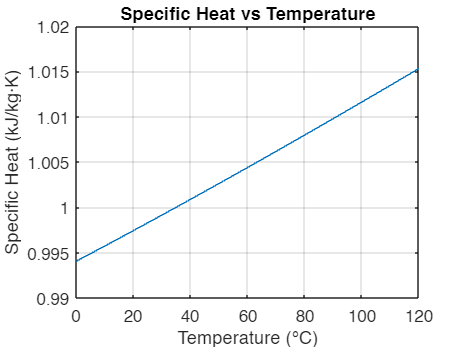

% Check by plotting
T1 = 0:120;
cp1 = 0.99403 + 1.671e-4*T1 + 9.7215e-8*T1.^2 - 9.5838e-11*T1.^3 + 1.9520e-14*T1.^4;
plot(T1, cp1)
xlabel('Temperature (°C)')
ylabel('Specific Heat (kJ/kg·K)')
title('Specific Heat vs Temperature')
grid on


x1 = 0; xu = 120; es = 1;
cp = @(T) 0.99403 + 1.671e-4*T + 9.7215e-8*T^2 - 9.5838e-11*T^3 + 1.9520e-14*T^4;
[root_b,relErr_b,iter_b] = bisect(cp,x1,xu,es)

Error using bisect (line 20)
no sign change

[root_f,relErr_f,iter_f] = falsepos(func,x1,xu,0.01)